# Agrupación de columna

 Clustering no supervisado para agrupar regímenes operativos en columnas de destilación.

## 0 Limpieza

clear
clc

## 1 Importación de datos

Lectura de datos

data=readtable("Columna_Destilacion.csv")

data = 150×3 table
    Reflujo    Presion_atm    Pureza_Porcentaje
    _______    ___________    _________________

    3.2032        1.0883           98.758      
    3.8326        1.1517           86.177      
    2.1636        1.4263           93.837      
    3.0433       0.99224           93.078      
    4.5718        1.4281           94.109      
    4.5852        1.3794           92.605      
    1.5023         1.483           92.803      
     1.829        1.1206            97.16      
    1.2059         1.023           91.328      
    2.7632        1.0443            92.49      
    1.1195        1.3967           94.673      
    2.8273        1.4791           86.253      
    3.5966        1.3193           91.047      
    2.1139        1.1895            86.43      
     3.705        1.0722           86.929      
    3.3635        1.4002            85.03      


## 2 Organización y Preprocesamiento

Normalización de datos

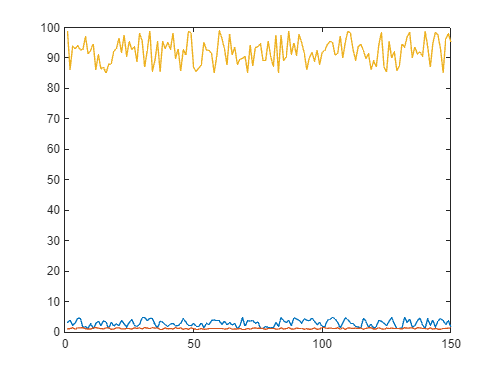

x=data{:,:};
X = normalize(data{:,:});
plot(x)

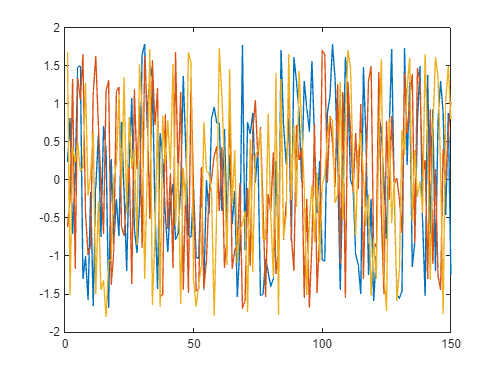

plot(X)

## 4 Creación del modelo

clusters=4;
[idx, C] = kmeans(X,clusters);

### Visualización

scatter3(X(:,1), X(:,2), X(:,3), 40, idx, 'filled');
centros=C;
centros(end+1,:)=centros(1,:)

centros =    -0.6959   -0.7981    0.2688
   -0.7914    1.0760    0.5109
    1.0816   -0.0550    0.5617
   -0.0635    0.0283   -1.2456
   -0.6959   -0.7981    0.2688


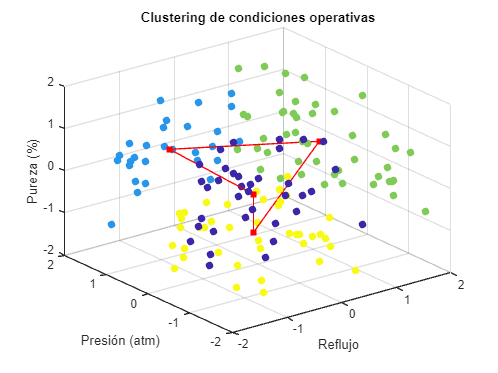

hold on
plot3(centros(:,1),centros(:,2),centros(:,3),'-rs','MarkerFaceColor','r')
hold off
xlabel('Reflujo');
ylabel('Presión (atm)');
zlabel('Pureza (%)');
title('Clustering de condiciones operativas');
grid on